close all;
clear all;
clc;

imdsTrain = imageDatastore("FaceData_Train",'IncludeSubfolders',true,...
    'LabelSource','none');

files = imdsTrain.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTrain.Labels = categorical(labels);

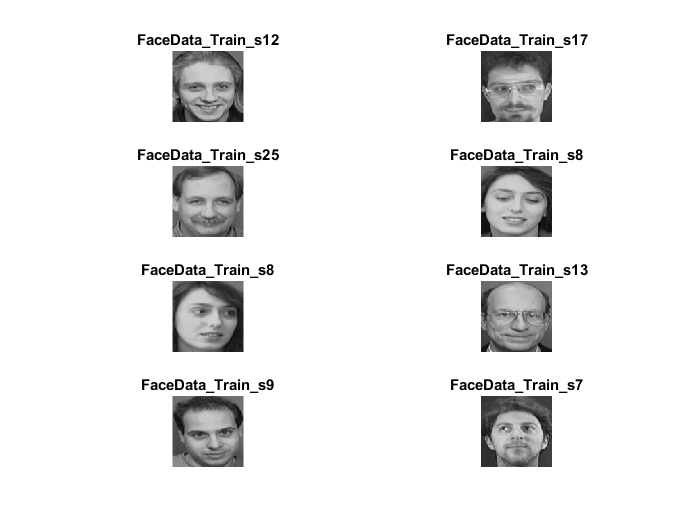

indexRandomImage = randperm(numel(imdsTrain.Files),8);

for i = 1:numel(indexRandomImage)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,indexRandomImage(i)))
    title(imdsTrain.Labels(indexRandomImage(i)), "Interpreter","none");
end

batchSize = 10;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);

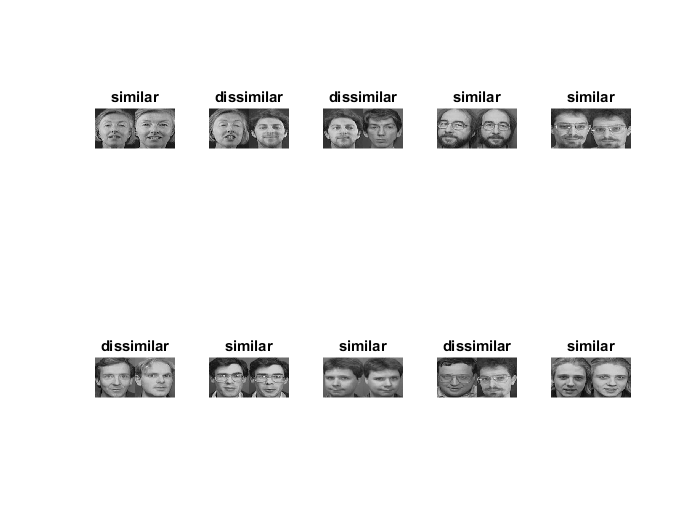

for i = 1:batchSize    
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(2,5,i)  
    photo1 = cast(pairImage1(:,:,1,i), 'uint8');
    photo2 = cast(pairImage2(:,:,1,i), 'uint8');
    imshow([photo1 photo2]);
    title(s)
end

layers = [
    imageInputLayer([105 105 1],'Name','input1','Normalization','none')
    convolution2dLayer(10,64,'Name','conv1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu1')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool1')
    convolution2dLayer(7,128,'Name','conv2','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu2')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool2')
    convolution2dLayer(4,128,'Name','conv3','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu3')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool3')
    convolution2dLayer(5,256,'Name','conv4','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu4')
    fullyConnectedLayer(4096,'Name','fc1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')];

lgraph = layerGraph(layers);

dlnet = dlnetwork(lgraph);

fcWeights = dlarray(0.01*randn(1,4096));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

numIterations = 500;
miniBatchSize = 32;

learningRate = 6e-5;
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];
gradDecay = 0.9;
gradDecaySq = 0.99;

executionEnvironment = "cpu";

plots = "training-progress";

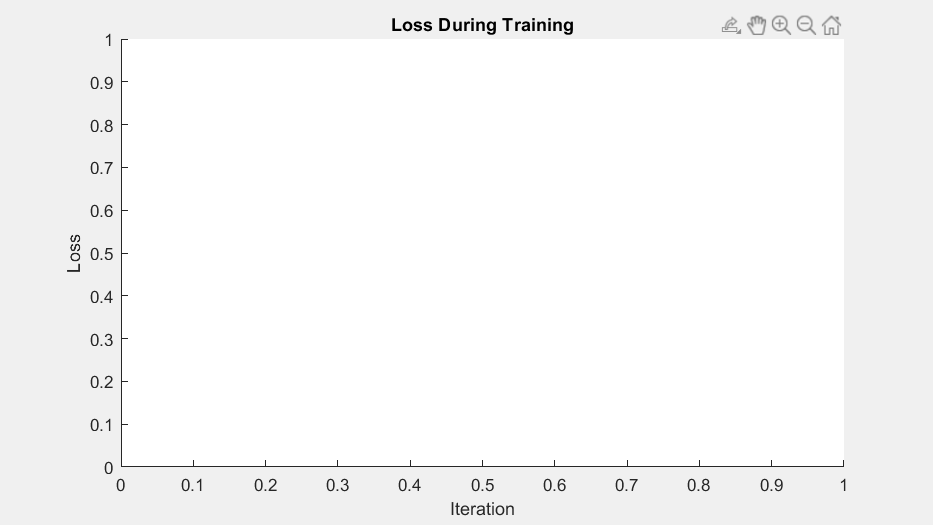

plotRatio = 16/9;

if plots == "training-progress"
    trainingPlot = figure;
    trainingPlot.Position(3) = plotRatio*trainingPlot.Position(4);
    trainingPlot.Visible = 'on';
    
    trainingPlotAxes = gca;
    
    lineLossTrain = animatedline(trainingPlotAxes);
    xlabel(trainingPlotAxes,"Iteration")
    ylabel(trainingPlotAxes,"Loss")
    title(trainingPlotAxes,"Loss During Training")
end

% Loop over mini-batches.
for iteration = 1:numIterations
    %epoch
    disp("Epoch = "+int2str(iteration));
    
    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data
    dlX1 = dlarray(single(X1),'SSCB');
    dlX2 = dlarray(single(X2),'SSCB');
       
    % Evaluate the model gradients and the generator state using
    % dlfeval and the modelGradients function listed at the end of the
    % example.
    [gradientsSubnet, gradientsParams,loss] = dlfeval(@modelGradients,dlnet,fcParams,dlX1,dlX2,pairLabels);
    lossValue = double(gather(extractdata(loss)));
    
    % Update the Siamese subnetwork parameters.
    [dlnet,trailingAvgSubnet,trailingAvgSqSubnet] = ...
        adamupdate(dlnet,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);
    
    % Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = ...
        adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);
      
    % Update the training loss progress plot.
    if plots == "training-progress"
        addpoints(lineLossTrain,iteration,lossValue);
    end
    drawnow;
end

Epoch = 1


Error using matlab.graphics.animation.AnimatedLine/addpoints
Value must be a handle.

imdsTest = imageDatastore("FaceData_Test", ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');    

files = imdsTest.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTest.Labels = categorical(labels);

numClasses = numel(unique(imdsTest.Labels))

numClasses = 8

accuracy = zeros(1,5);
accuracyBatchSize = 150;

for i = 1:5
    
    % Extract mini-batch of image pairs and pair labels
    [XAcc1,XAcc2,pairLabelsAcc] = getSiameseBatch(imdsTest,accuracyBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data.
    dlXAcc1 = dlarray(single(XAcc1),'SSCB');
    dlXAcc2 = dlarray(single(XAcc2),'SSCB');
         
    % Evaluate predictions using trained network
    dlY = predictSiamese(dlnet,fcParams,dlXAcc1,dlXAcc2);
   
    % Convert predictions to binary 0 or 1
    Y = gather(extractdata(dlY));
    Y = round(Y);
    
    % Compute average accuracye for the minibatch
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

% Compute accuracy over all minibatches
averageAccuracy = mean(accuracy)*100

averageAccuracy = 75.0667

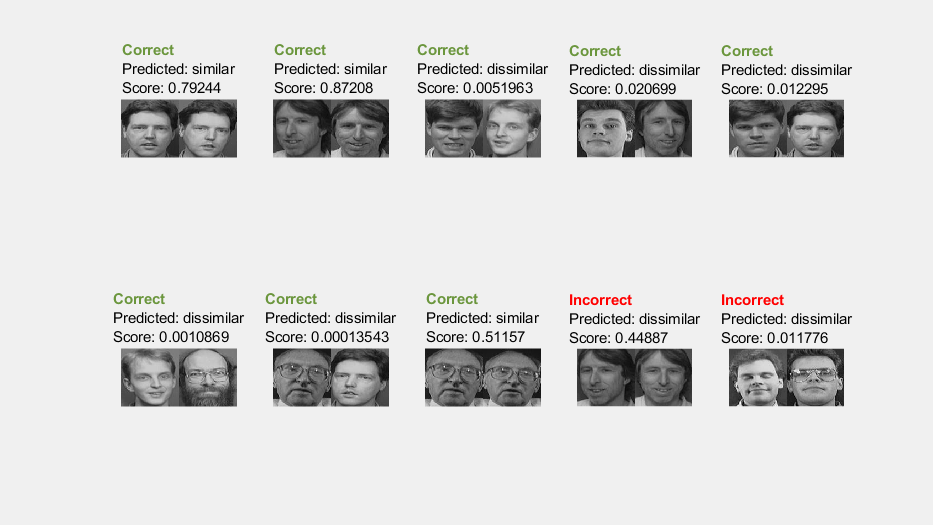

testBatchSize = 10;

[XTest1,XTest2,pairLabelsTest] = getSiameseBatch(imdsTest,testBatchSize);
    
% Convert test batch of data to dlarray. Specify the dimension labels
% 'SSCB' (spatial, spatial, channel, batch) for image data and 'CB' 
% (channel, batch) for labels
dlXTest1 = dlarray(single(XTest1),'SSCB');
dlXTest2 = dlarray(single(XTest2),'SSCB');

% Calculate the predicted probability
dlYScore = predictSiamese(dlnet,fcParams,dlXTest1,dlXTest2);
YScore = gather(extractdata(dlYScore));

% Convert predictions to binary 0 or 1
YPred = round(YScore);    

% Extract data to plot
XTest1 = extractdata(dlXTest1);
XTest2 = extractdata(dlXTest2);

% Plot images with predicted label and predicted score
testingPlot = figure;
testingPlot.Position(3) = plotRatio*testingPlot.Position(4);
testingPlot.Visible = 'on';
    
for i = 1:numel(pairLabelsTest)
     
    if YPred(i) == 1
        predLabel = "similar";
    else
        predLabel = "dissimilar" ;
    end
    
    if pairLabelsTest(i) == YPred(i)
        testStr = "\bf\color{darkgreen}Correct\rm\newline";
        
    else
        testStr = "\bf\color{red}Incorrect\rm\newline";
    end
    
    photo1 = cast(XTest1(:,:,:,i), 'uint8');
    photo2 = cast(XTest2(:,:,:,i), 'uint8');
    
    subplot(2,5,i)        
    imshow([photo1 photo2]);        
    
    title(testStr + "\color{black}Predicted: " + predLabel + "\newlineScore: " + YScore(i)); 
end